# Lab 5: Cross-Device OFDM Transmission

## [Part 1]

clear;
N = 64;
Ncp = 16;
fc = 915*1e6;
fs = 1e6;

pilot_bins = [-21 -7 7 21];
used_bins  = setdiff([-26:-1 1:26], pilot_bins);
idx = @(k) k + N/2 + 1;
N_samp = 100;
pilot_bits = randi([0 1], numel(pilot_bins), 1);
pilot = pskmod(pilot_bits, 2);

PPM = 5;
df_CFO = fc*PPM/1e6;

### training symbols generation

sts_bins = [-24 -20 -16 -12 -8 -4 4 8 12 16 20 24];
sts_signs = [ 1 -1  1 -1 -1  1 -1 -1  1  1  1  1];  
    
% Map to FFT bins
X_sts = zeros(N,1);
for i = 1:numel(sts_bins)
    X_sts(idx(sts_bins(i))) = sts_signs(i) * (1+1j);
end
X_sts = X_sts * sqrt(13/6);
    
x_sts_64 = ifft(ifftshift(X_sts), N);
x_sts_16 = x_sts_64(1:Ncp);
x_sts = repmat(x_sts_16, 10, 1);

lts_bins = [-26:-1 1:26];
lts_signs = [ ...
1,  1, -1, -1,  1,  1, -1,  1, -1,  1,  1,  1,  1,  1,  1, -1, -1,  1,  1, -1,  1, -1,  1,  1,  1,  1, ...
1, -1, -1,  1,  1, -1,  1, -1,  1, -1, -1, -1, -1, -1,  1,  1, -1, -1,  1, -1,  1, -1,  1,  1,  1,  1];
    
X_lts = zeros(N,1);
for i = 1:numel(lts_bins)
    X_lts(idx(lts_bins(i))) = lts_signs(i);
end
    
x_lts = ifft(ifftshift(X_lts), N);

## **(1) Network Configuration**

## **(2) Receive Strategy (not done)**

- Append zeros to the transmitted frame.

## **(3) **

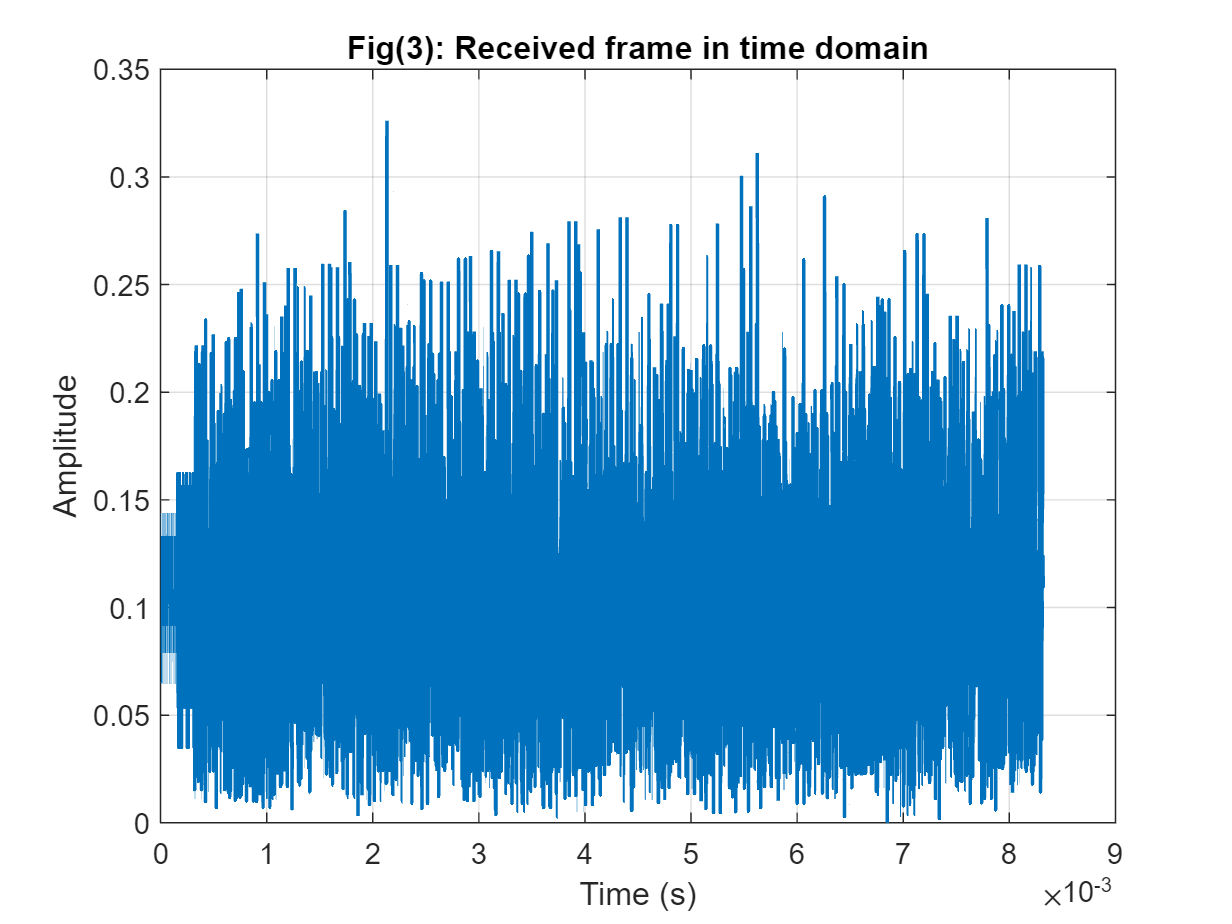

data_bits = randi([0 1], numel(used_bins)*log2(4), N_samp);
x_tx = OFDM(data_bits, N_samp, pilot, idx(pilot_bins), idx(used_bins), N, Ncp, 4);
x_tx_TS = add_TS(x_tx, x_sts, x_lts);
x_tx_ext = [zeros(100,1); x_tx_TS; zeros(100,1)];

% x_rx = USRP_channel_new(x_tx_ext, x_lts, x_sts);
x_rx = x_tx_TS;
figure;
t_axis = (0:numel(x_tx_TS)-1)/fs;
plot(t_axis, abs(x_rx), 'LineWidth', 1.2);
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('Fig(3): Received frame in time domain');

## (4) Received Constellations without CFO Correction

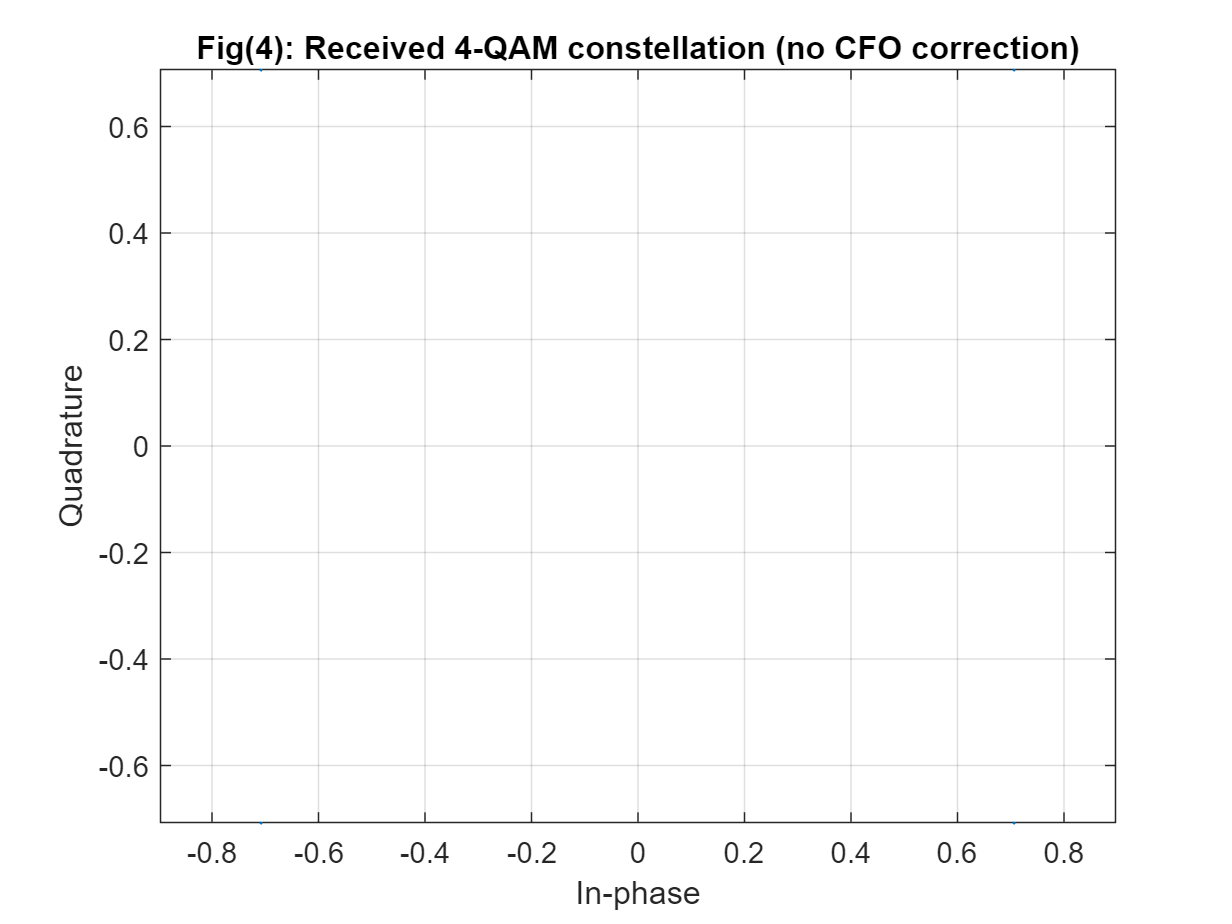

H_LTS = channel_est(x_rx(161:320), x_lts);
frame_symb = x_rx(321:end);
X_est = zeros(48, N_samp);
for n = 1:N_samp
    y_symb = frame_symb(80*(n-1)+1+16: 80*n);
    Y_symb = fftshift(fft(y_symb));
    X_est_temp = Y_symb(idx(used_bins)) ./ H_LTS(idx(used_bins));
    X_est(:, n) = X_est_temp;
end

figure;
plot(real(X_est(:)), imag(X_est(:)), '.', 'MarkerSize', 2);
grid on; axis equal;
xlabel('In-phase'); ylabel('Quadrature');
title(sprintf('Fig(4): Received 4-QAM constellation (no CFO correction)'));

## (5) CFO estimation by two consecutive LTS

L_lts = 64;
s = 160+L_lts/2;
lts1 = x_rx(s+1:s+L_lts);
lts2 = x_rx(s+L_lts+1:s+L_lts*2);

p_lts = sum(conj(lts1) .* lts2);
phi_lts = angle(p_lts);
df_est_lts = phi_lts*fs/(2*pi*L_lts);
fprintf('Estimated CFO from two consecutive LTS is %.4f.', df_est_lts);

Estimated CFO from two consecutive LTS is 0.0000.


err = abs(df_est_lts / df_CFO - 1);
fprintf('CFO estimation error is %.4f%%.', err*100);

CFO estimation error is 100.0000%.

CFO is estimated from two consecutive LTS. The method is identical to CFO estimation in lab4.

## (6) CFO correction

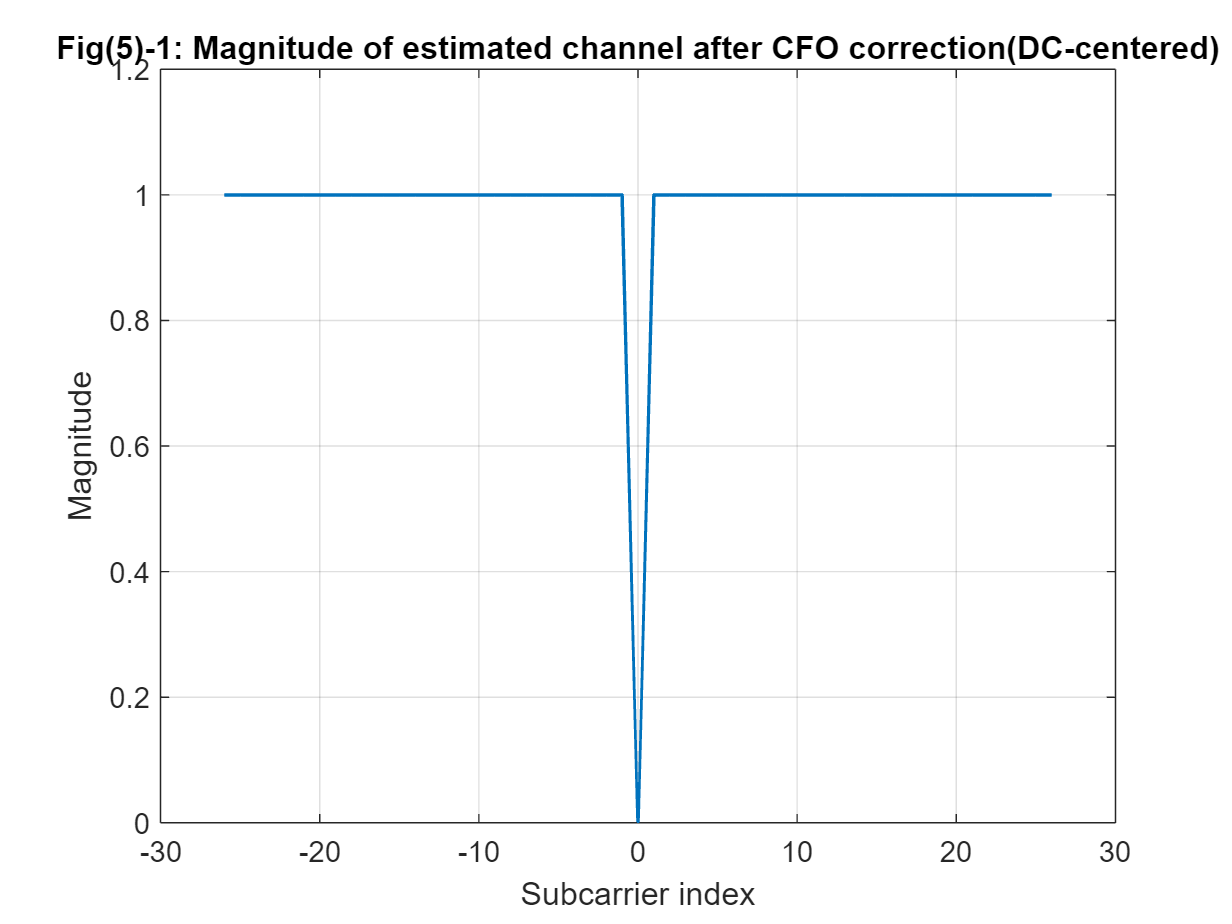

CFO_corr = exp(-1j*2*pi*(0:numel(x_rx)-1)*df_est_lts/fs).';
x_rx_CFO = x_rx .* CFO_corr;
H_CFO = channel_est(x_rx_CFO(161:320), x_lts);

figure;
plot((-26:26), abs(H_CFO(idx(-26):idx(26))), 'LineWidth', 1.2);
grid on;
xlabel('Subcarrier index');
ylabel('Magnitude');
title('Fig(5)-1: Magnitude of estimated channel after CFO correction(DC-centered)');

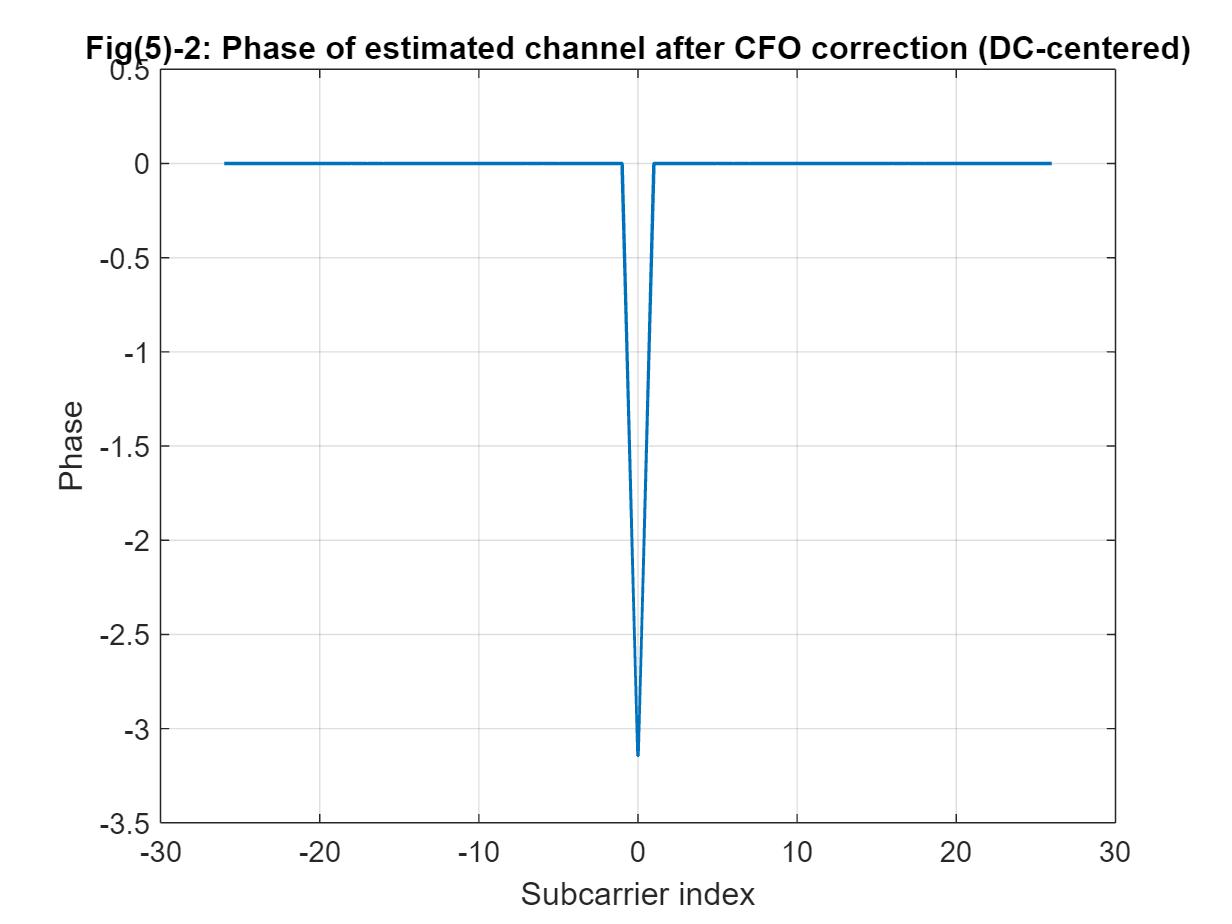


figure;
plot((-26:26), angle(H_CFO(idx(-26):idx(26))), 'LineWidth', 1.2);
grid on;
xlabel('Subcarrier index');
ylabel('Phase');
title('Fig(5)-2: Phase of estimated channel after CFO correction (DC-centered)');

The magnitude looks similar before and after CFO. After CFO, the plot of magnitude seems smoother. 

The phase after CFO is still a linear function; the slope becomes slightly smaller (not significant).

## (7) Equalization

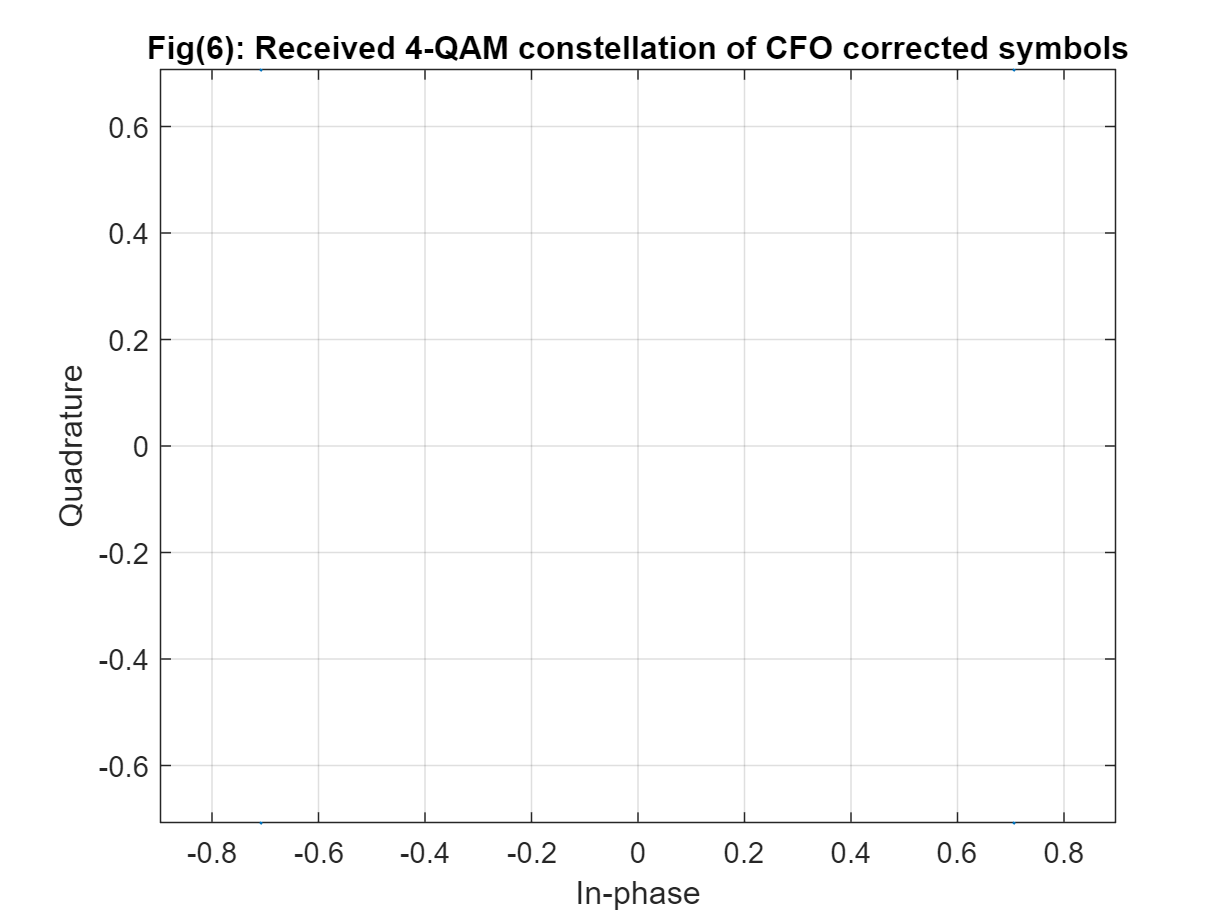

frame_symb_CFO = x_rx_CFO(321:end); % CFO corrected
X_est_CFO = zeros(48, N_samp);
for n = 1:N_samp
    y_symb = frame_symb_CFO(80*(n-1)+1+16: 80*n);
    Y_symb = fftshift(fft(y_symb));
    X_est_temp = Y_symb ./ H_CFO;
    X_est_CFO(:, n) = X_est_temp(idx(used_bins));
end

figure;
plot(real(X_est_CFO(:)), imag(X_est_CFO(:)), '.', 'MarkerSize', 2);
grid on; axis equal;
xlabel('In-phase'); ylabel('Quadrature');
title(sprintf('Fig(6): Received 4-QAM constellation of CFO corrected symbols'));

The CFO-corrected constellation become distinguishable. Four clear groups appear. However, there still exists a little phase offset.

## (8) Pilot-Assisted Constellation

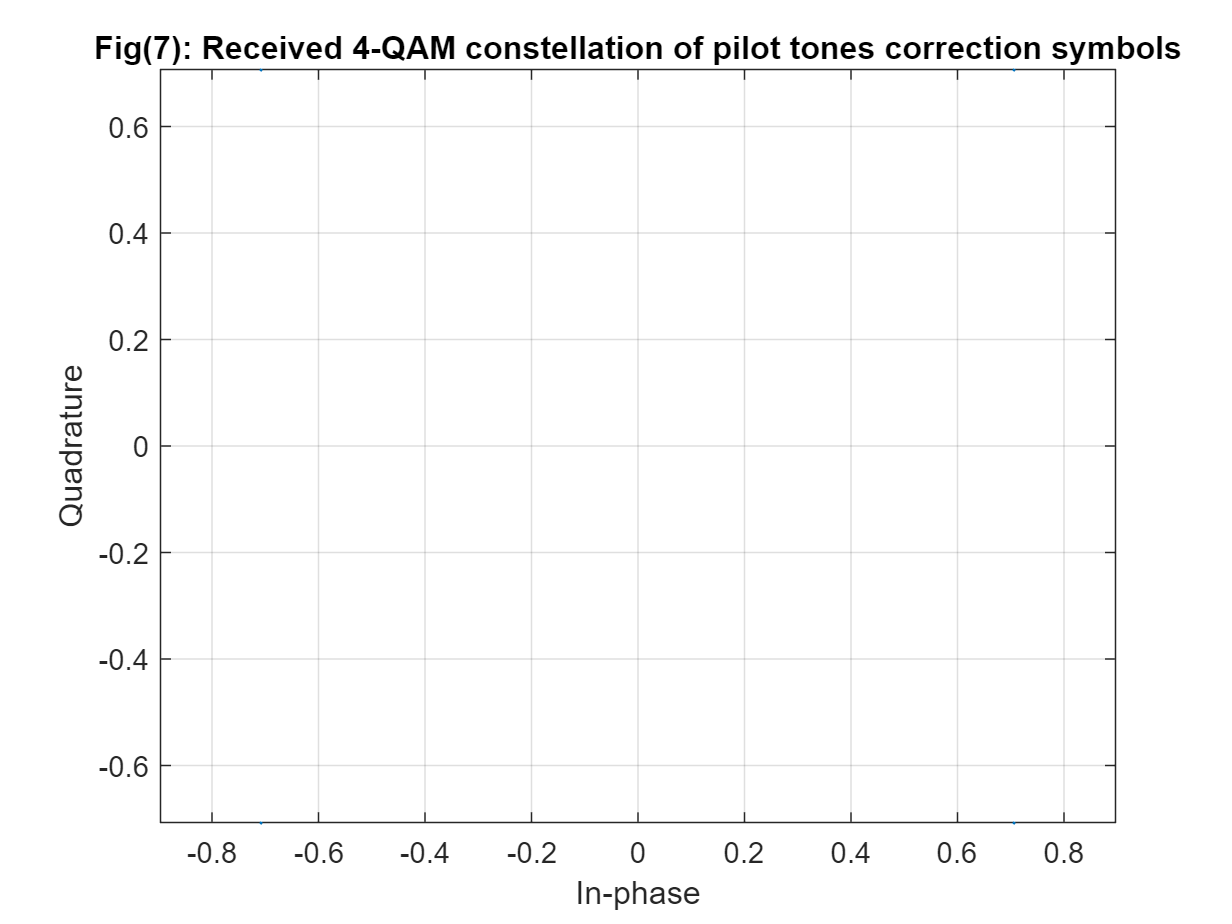

frame_symb_CFO = x_rx_CFO(321:end);
X_est_CFO = zeros(48, N_samp);
for n = 1:N_samp
    y_symb = frame_symb_CFO(80*(n-1)+1+16: 80*n);
    Y_symb = fftshift(fft(y_symb));
    X_est_temp = Y_symb ./ H_CFO;
    pilot_est = X_est_temp(idx(pilot_bins));
    corr = mean(pilot_est./pilot);
    X_est_CFO(:, n) = X_est_temp(idx(used_bins))/corr;
end

figure;
plot(real(X_est_CFO(:)), imag(X_est_CFO(:)), '.', 'MarkerSize', 2);
grid on; axis equal;
xlabel('In-phase'); ylabel('Quadrature');
title(sprintf('Fig(7): Received 4-QAM constellation of pilot tones correction symbols'));

## (9) Demodulation

X_rx_vec_4 = X_est_CFO(:);
bits_demod_4 = qamdemod(X_rx_vec_4, 4, 'gray', OutputType='bit', UnitAveragePower=true);
BER_4qam = ber_cal(bits_demod_4, data_bits(:));
fprintf("BER of 4-QAM demodulation is %.4f.", BER_4qam);

BER of 4-QAM demodulation is 0.0000.

## (10) 16-QAM

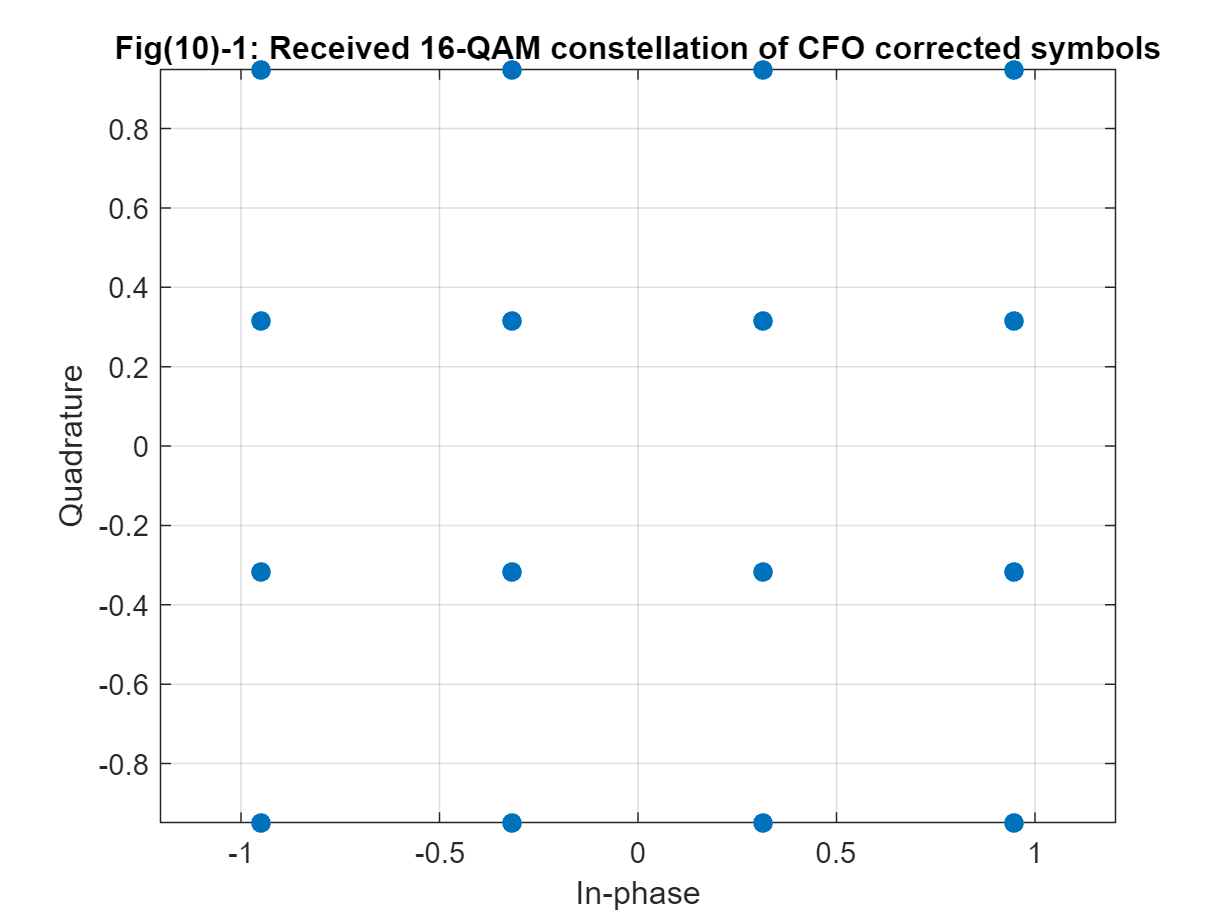

data_bits_16 = randi([0 1], numel(used_bins)*log2(16), N_samp);
x_tx_16 = OFDM(data_bits_16, N_samp, pilot, idx(pilot_bins), idx(used_bins), N, Ncp, 16);
x_tx_TS_16 = add_TS(x_tx_16, x_sts, x_lts);
x_tx_ext_16 = [zeros(100,1); x_tx_TS_16; zeros(100,1)];
% x_rx_16 = USRP_channel_new(x_tx_ext_16, x_lts, x_sts);
x_rx_16 = x_tx_TS_16;

L_lts = 64;
s = 160+L_lts/2;
lts1 = x_rx_16(s+1:s+L_lts);
lts2 = x_rx_16(s+L_lts+1:s+L_lts*2);

p_lts = sum(conj(lts1) .* lts2);
phi_lts = angle(p_lts);
df_est_lts = phi_lts*fs/(2*pi*L_lts);

CFO_corr_16 = exp(-1j*2*pi*(0:numel(x_rx_16)-1)*df_est_lts/fs).';
x_rx_CFO_16 = x_rx_16 .* CFO_corr_16;


H_CFO_16 = channel_est(x_rx_CFO_16(161:320), x_lts);
frame_symb_CFO_16 = x_rx_CFO_16(321:end); % CFO corrected

X_est_CFO_16 = zeros(48, N_samp);
X_est_equalized = zeros(48, N_samp);
for n = 1:N_samp
    y_symb = frame_symb_CFO_16(80*(n-1)+1+16: 80*n);
    Y_symb = fftshift(fft(y_symb));
    X_est_temp = Y_symb ./ H_CFO_16;
    X_est_CFO_16(:,n)     = Y_symb(idx(used_bins));
    X_est_equalized(:, n) = X_est_temp(idx(used_bins));
end

figure;
plot(real(X_est_CFO_16(:)), imag(X_est_CFO_16(:)), '.', 'MarkerSize', 2);
grid on; axis equal;
xlabel('In-phase'); ylabel('Quadrature');
title(sprintf('Fig(10)-1: Received 16-QAM constellation of CFO corrected symbols'));

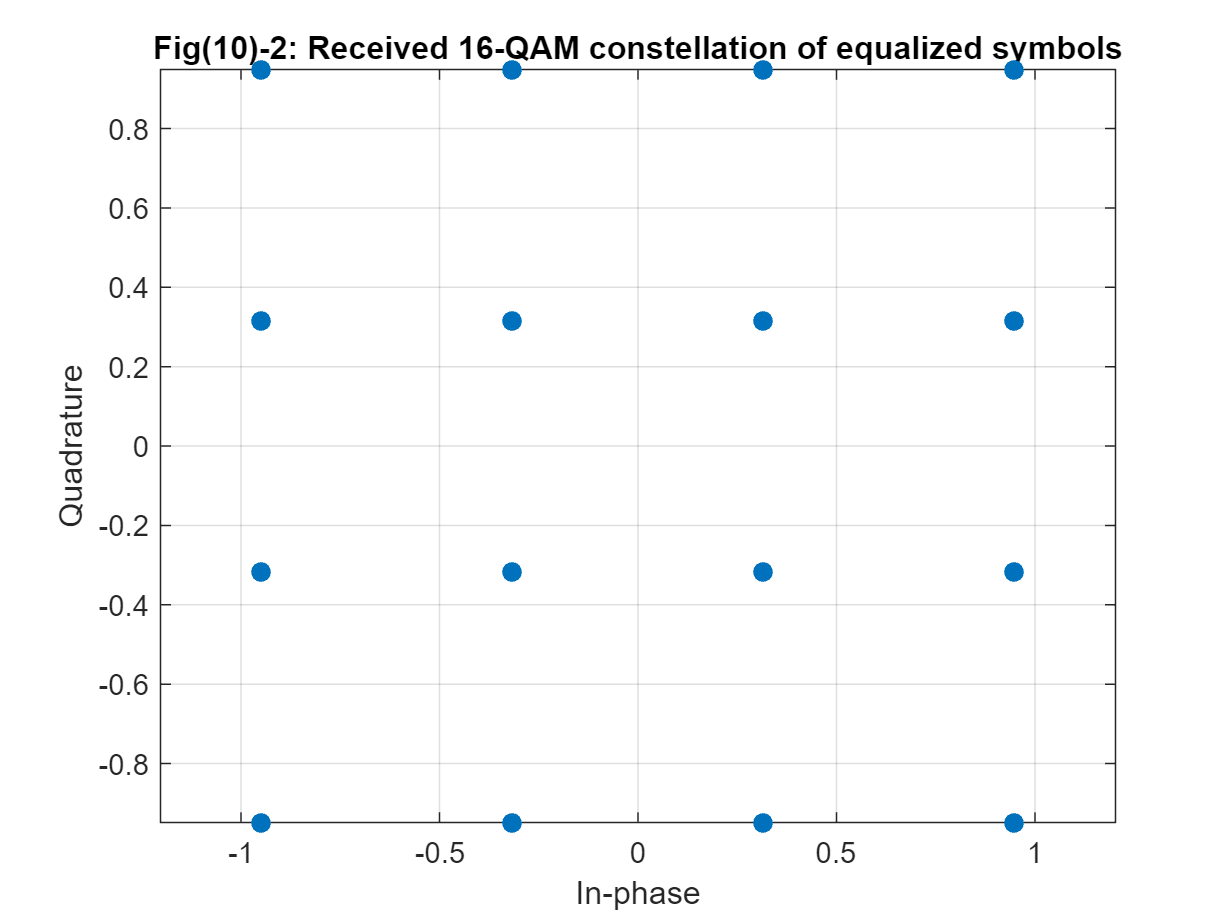


figure;
plot(real(X_est_equalized(:)), imag(X_est_equalized(:)), '.', 'MarkerSize', 20);
grid on; axis equal;
xlabel('In-phase'); ylabel('Quadrature');
title(sprintf('Fig(10)-2: Received 16-QAM constellation of equalized symbols'));

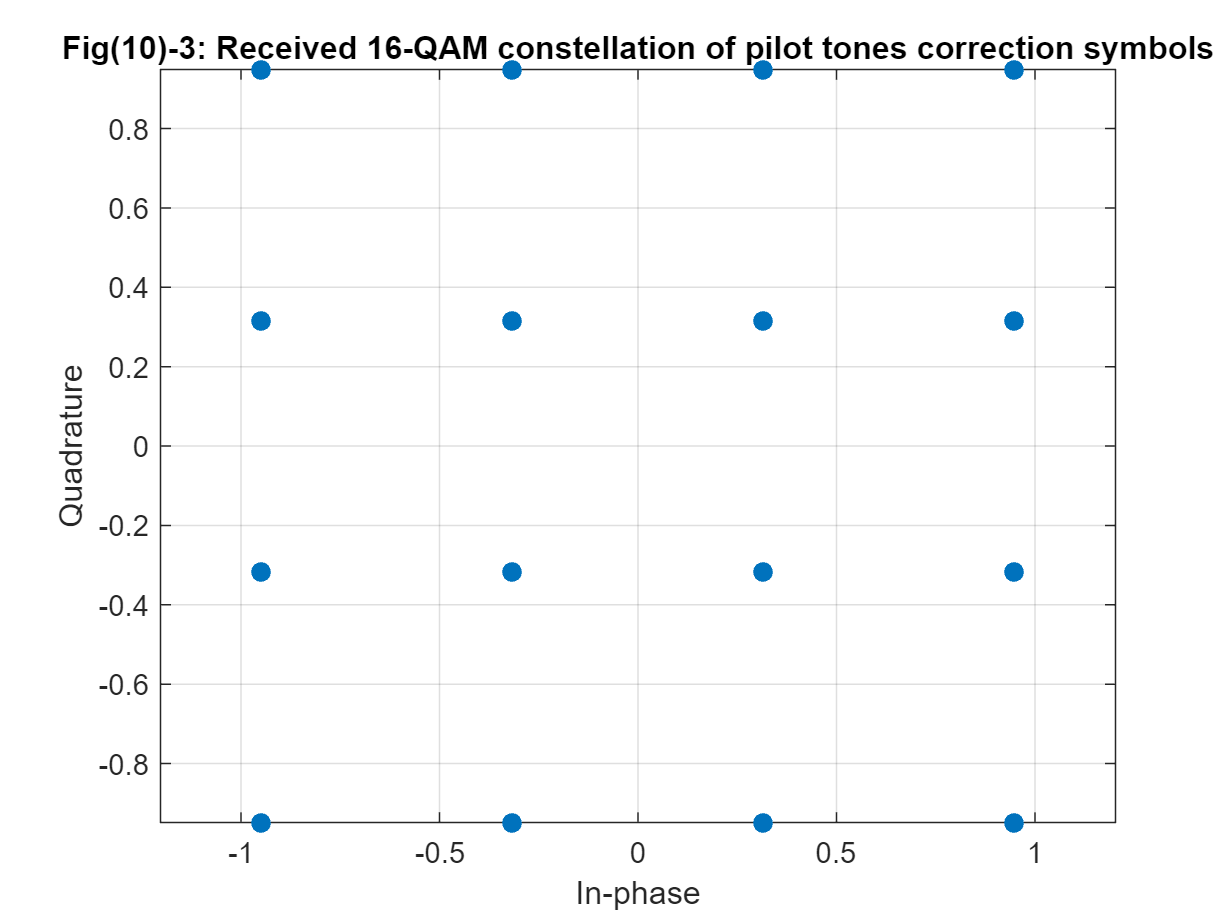


X_est_CFO_pilot = zeros(48, N_samp);
for n = 1:N_samp
    y_symb = frame_symb_CFO_16(80*(n-1)+1+16: 80*n);
    Y_symb = fftshift(fft(y_symb));
    X_est_temp = Y_symb ./ H_CFO_16;
    pilot_est = X_est_temp(idx(pilot_bins));
    corr = mean(pilot_est./pilot);
    X_est_CFO_pilot(:, n) = X_est_temp(idx(used_bins))/corr;
end

figure;
plot(real(X_est_CFO_pilot(:)), imag(X_est_CFO_pilot(:)), '.', 'MarkerSize', 20);
grid on; axis equal;
xlabel('In-phase'); ylabel('Quadrature');
title(sprintf('Fig(10)-3: Received 16-QAM constellation of pilot tones correction symbols'));

## (11) Demodulation

X_rx_vec_16 = X_est_CFO_pilot(:);
bits_demod_16 = qamdemod(X_rx_vec_16, 16, 'gray', OutputType='bit', UnitAveragePower=true);
BER_16qam = ber_cal(bits_demod_16, data_bits_16(:));
fprintf("BER of 16-QAM demodulation is %.4f.", BER_16qam);

BER of 16-QAM demodulation is 0.0000.

## (12) BER of 20 Frames

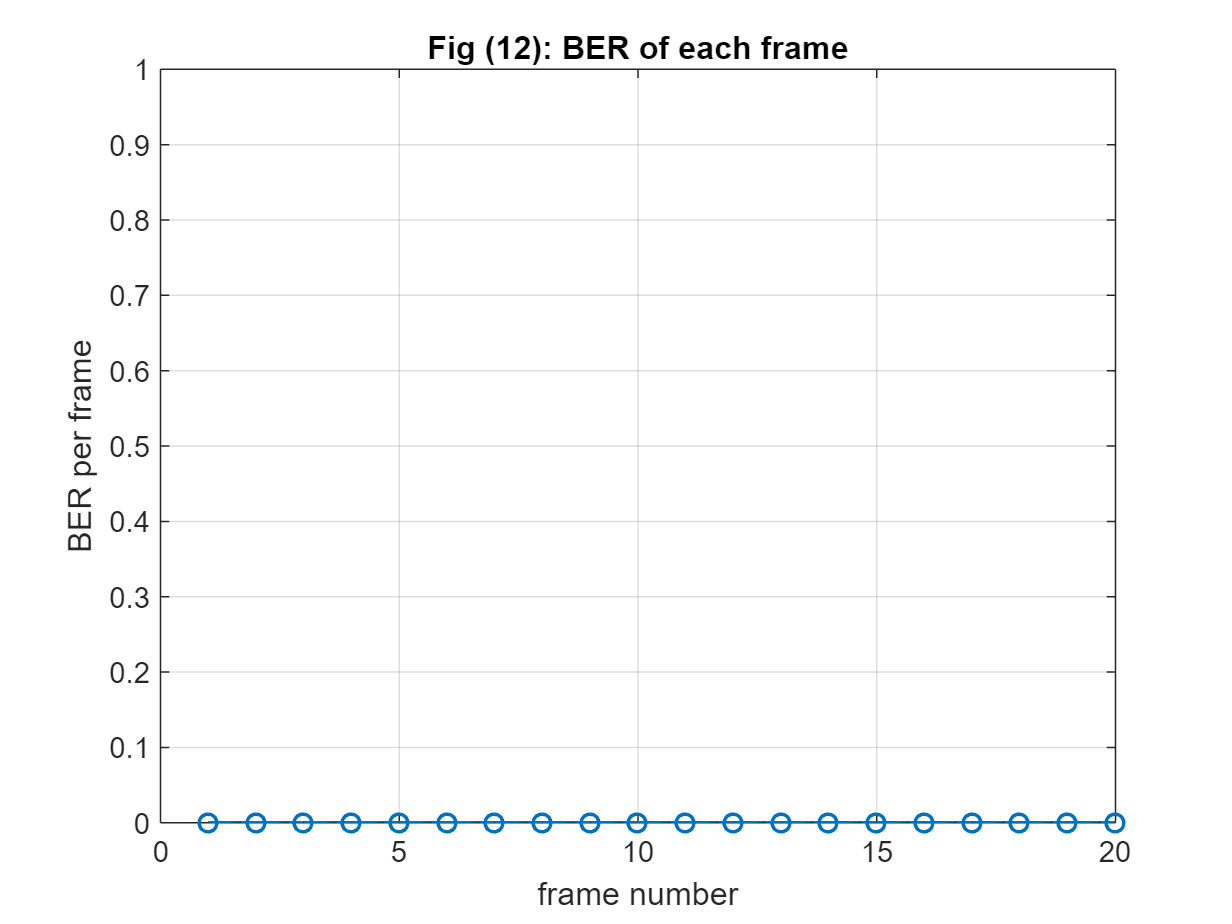

iter = 20;
BER_array = zeros(iter, 1);

for i = 1:iter
    data_bits_16_loop = randi([0 1], numel(used_bins)*log2(16), N_samp);
    x_tx_16 = OFDM(data_bits_16_loop, N_samp, pilot, idx(pilot_bins), idx(used_bins), N, Ncp, 16);
    x_tx_TS_16 = add_TS(x_tx_16, x_sts, x_lts);
    x_tx_ext_16 = [zeros(100,1); x_tx_TS_16; zeros(100,1)];
    % x_rx_16 = USRP_channel(x_tx_ext_16, x_lts, x_sts);
    x_rx_16 = x_tx_TS_16;

    L_lts = 64;
    s = 160+L_lts/2;
    lts1 = x_rx_16(s+1:s+L_lts);
    lts2 = x_rx_16(s+L_lts+1:s+L_lts*2);
    
    p_lts = sum(conj(lts1) .* lts2);
    phi_lts = angle(p_lts);
    df_est_lts = phi_lts*fs/(2*pi*L_lts);
    
    CFO_corr_16 = exp(-1j*2*pi*(0:numel(x_rx_16)-1)*df_est_lts/fs).';
    x_rx_CFO_16 = x_rx_16 .* CFO_corr_16;
    
    
    H_CFO_16 = channel_est(x_rx_CFO_16(161:320), x_lts);
    frame_symb_CFO_16 = x_rx_CFO_16(321:end); % CFO corrected
    
    X_est_CFO_pilot = zeros(48, N_samp);
    for n = 1:N_samp
        y_symb = frame_symb_CFO_16(80*(n-1)+1+16: 80*n);
        Y_symb = fftshift(fft(y_symb));
        X_est_temp = Y_symb ./ H_CFO_16;
        pilot_est = X_est_temp(idx(pilot_bins));
        corr = mean(pilot_est./pilot);
        X_est_CFO_pilot(:, n) = X_est_temp(idx(used_bins))/corr;
    end

    X_rx_vec_16 = X_est_CFO_pilot(:);
    bits_demod_16_loop = qamdemod(X_rx_vec_16, 16, 'gray', OutputType='bit', UnitAveragePower=true);
    BER_array(i) = ber_cal(bits_demod_16_loop, data_bits_16_loop(:));
end

figure;
plot(1:20, BER_array, '-o', 'LineWidth', 1.2);
grid on;
xlabel('frame number');
ylabel('BER per frame');
ylim([0, 1]);
title('Fig (12): BER of each frame');


BER_mean = sum(BER_array) / iter;
fprintf('The total BER for 20 frames is %.4f.', BER_mean);

The total BER for 20 frames is 0.0000.

Functions

function [radio_Tx, radio_Rx] = USRP_init(rx_length)
% USRP init for N200/N210/USRP2 with 10 MS/s host rate
    platform  = "N200/N210/USRP2";
    address   = '192.168.10.2';
    fc = 915*1e6;     % center frequency
    txGain_dB = 5;         % tune as needed (avoid clipping)
    rxGain_dB = 20;

    radio_Tx = comm.SDRuTransmitter( ...
        'Platform',          platform, ...
        'IPAddress',         address, ...
        'CenterFrequency',   fc, ...
        'Gain',              txGain_dB, ...
        'MasterClockRate',   100e6, ...
        'InterpolationFactor', 100);

    radio_Rx = comm.SDRuReceiver( ...
        'Platform',          "B210", ...
        'SerialNum',        "319BF05", ...
        'CenterFrequency',   fc, ...
        'Gain',              rxGain_dB, ...
        'SamplesPerFrame',   rx_length, ...
        'MasterClockRate',   20e6, ...
        'DecimationFactor',  20, ...
        'OutputDataType',    'double');
end

function x_cp = OFDM(data_bits, N_samp, pilot, pilot_bins, used_bins, FFT_size, cp_size, qam)
    data_symb = qammod(data_bits, qam, 'gray', InputType='bit', UnitAveragePower=true);
    
    xcp_all = complex(zeros(FFT_size+cp_size, N_samp));
    
    for n = 1:N_samp
        % ----- 1) Build frequency-domain X for one OFDM symbol -----
        X = zeros(FFT_size,1);
    
        % pilots (BPSK ±1)
        X(pilot_bins) = pilot;
    
        % data (take this symbol's mapped constellation)
        X(used_bins) = data_symb(:, n);
    
        % ----- 2) IFFT -> time domain -----
        x = ifft(ifftshift(X));                % 64 samples
    
        % ----- 3) Add cyclic prefix -----
        xcp_all(:, n) = [x(end-cp_size+1:end); x];
    end
    x_cp = xcp_all(:);
end

function x_ts = add_TS(x_tx, x_sts, x_lts)
    
    CP_LTS = 16;              
    x_lts_field = [x_lts(end-CP_LTS+1:end); x_lts(end-CP_LTS+1:end); x_lts; x_lts];

    x_ts = [x_sts; x_lts_field; x_tx];
end

function H_LTS = channel_est(frame_LTS, x_lts)
    X_LTS = fftshift(fft(x_lts));
    frame_lts1 = frame_LTS(32+1:32+64);
    frame_lts2 = frame_LTS(end-64+1:end);
    Y_LTS1 = fftshift(fft(frame_lts1));
    Y_LTS2 = fftshift(fft(frame_lts2));
    H_LTS = (Y_LTS1+Y_LTS2)/2 .* X_LTS;
end

function BER = ber_cal(x, y)
    BER = mean(x ~= y);
end

function x_rx = USRP_channel_new(x_tx_CFO, x_lts, x_sts)
    Fs = 1e6; % host-side rate (matches Interp/Decim=10 for 100 MHz) 
    Ns_frame = numel(x_tx_CFO); 
    % ---- Build one TX packet per iteration: frame + guard zeros (fixed length) ---- 
    guard_len = 0; % 80 us of silence @ 10 MS/s (tune 400–2000 as needed) 
    tx_one = [x_tx_CFO(:); zeros(guard_len,1)]; % complex column 
    Ltx = numel(tx_one); % ---- Backoff to avoid clipping at DAC ---- % 
    
    rx_length = 2.0*Ltx; 
    [radio_Tx, radio_Rx] = USRP_init(rx_length); 
    l = rx_length; 
    n = 2000;
    buffer = complex(zeros(n+30,rx_length)) ;
    THR_POW = 1e-4;
    found = false;
    det_idx = NaN;
    max_scan = n+50;
    % Transmit and receive for 50 frames 
    for k = 1:3
        step(radio_Rx);
    end
    for ii = 1 : max_scan 
        tunderrun = radio_Tx(tx_one); 
        [rcvdSignal, ~, toverflow] = step(radio_Rx); % buffer(ii,:) = real(rcvdSignal.' ); 
        buffer(ii,:) = rcvdSignal.' ; 
        received_power = mean(abs(rcvdSignal).^2);
        if ~found && received_power>THR_POW
            found = true;
            det_idx = ii;
            fprintf('Detected strong frame at ii=%d, P=%.3g > THR=%.3g\n', ii, received_power, THR_POW);
            break
        end
        if found
            break
        end
    end
    
    
    if found
        for jj = 1:30
            [rcvdSignal, ~, toverflow] = step(radio_Rx); %#ok<ASGLU>
            buffer(det_idx+jj,:) = rcvdSignal.';
        end
        last_idx = det_idx + 30;
    else
        % If not found, still capture some extra for inspection
        fprintf('No strong frame detected (THR=%.3g). Capturing 30 extra frames anyway.\n', THR_POW);
        for jj = 1:30
            [rcvdSignal, ~, toverflow] = step(radio_Rx); %#ok<ASGLU>
            buffer(max_scan+jj,:) = rcvdSignal.';
        end
        last_idx = max_scan + 30;
    end
    
    release(radio_Tx) 
    release(radio_Rx) 
    % ---- Quick health checks ---- 
    rx_peaks = max(abs(buffer(1:n,:)),[],2); 
    fprintf('TX peak after backoff: %.3f | median RX peak: %.3f\n', max(abs(tx_one)), median(rx_peaks));
    % fprintf('TX peak after backoff: %.3f | median RX peak: %.3f\n', max(abs(tx_one)), median(rx_peaks));
    
    % ---- Pick one received frame and plot with region markers (no correlation yet) ----
    buffer_squeezed = reshape(buffer.', 1, []).';
    Ncp_LTS = 32;        % LTS CP length (samples)
    ST_len = 16;        % short symbol length
    sts_len = 10*ST_len; % 10 repeats of 16
    LT_len = 64;        % one LTS body
    N = 64;
    extracted_piece = buffer_squeezed;
    x_received = extracted_piece(:).';         % ensure row vector
    
    % x_received = frame;
    
    % ---- LTS matched filter (time-reversed, conjugated) ----
    hL = conj(fliplr(x_lts));           % MF kernel
    yL_full = conv(x_received, hL, 'full');
    yL = yL_full(1:length(x_received));   % align length
    
    % ---- Two-peak comb: pick two adjacent LTS (LTS1 & LTS2) ----
    combL = zeros(1, 2*N);             % length = 128
    combL(1) = 1;
    combL(N+1) = 1;                          % second peak N samples later
    
    % Convolve comb with |yL| to score aligned double-LTS patterns
    zL_full = conv(yL, combL, 'full');
    zL= zL_full(numel(combL):end);        % align to x_received
    
    % ---- Peak detection & indices ----
    [~, zL_max_index] = max(zL);   
    idx_lts1  = zL_max_index;
    idx_lts_cp = idx_lts1 - Ncp_LTS;            % CP starts 32 samples before LTS1
    idx_sts = idx_lts_cp - sts_len;          % STS region start
    idx_data = idx_lts_cp + (Ncp_LTS + 2*N);  % start of data symbols
    
    % Bound to valid range
    clip = @(x) max(1, min(x, numel(x_received)));
    idx_lts1 = clip(idx_lts1);
    idx_lts_cp = clip(idx_lts_cp);
    idx_sts = clip(idx_sts);
    idx_data = clip(idx_data);
    
    idx_frame_start = idx_sts-100;
    
    idx_sts_one_frame = idx_sts - idx_frame_start + 1;
    idx_lts1_one_frame = idx_lts1 - idx_frame_start + 1;
    idx_lts_cp_one_frame = idx_lts_cp - idx_frame_start + 1;
    idx_data_one_frame = idx_data - idx_frame_start + 1;
    
    % x_received_one_frame = x_received(idx_frame_start:idx_frame_start+920-1);
    
    % t_us = (0:numel(x_received_one_frame)-1)/Fs * 1e6;
    t_us = (0:length(x_received)-1)/Fs * 1e6;

    % ---- Plot: LTS MF result & 2-peak score ----
    figure; hold on; grid on; box on;
    plot(t_us, real(zL),     'LineWidth', 1.2, 'DisplayName','Two-peak score z_L[n]');
    plot(t_us, real(yL), '-',        'LineWidth', 1.2, 'DisplayName','|LTS MF|');
    plot(t_us, x_received, '--', 'LineWidth', 1.0, 'DisplayName','|x_{rx}|');
    
    % Detected boundaries
    xline(t_us(idx_sts), 'y-', 'LineWidth',1.2, 'Label','detected STS start', ...
        'LabelHorizontalAlignment','left','HandleVisibility','off');
    xline(t_us(idx_lts_cp), 'm-', 'LineWidth',1.2, 'Label','detected LTS-CP start', ...
        'LabelHorizontalAlignment','left','HandleVisibility','off');
    xline(t_us(idx_lts1),   'g-', 'LineWidth',1.2, 'Label','detected LTS1 start', ...
        'LabelHorizontalAlignment','left','HandleVisibility','off');
    xline(t_us(idx_data),   'r-', 'LineWidth',1.2, 'Label','detected DATA start', ...
        'LabelHorizontalAlignment','left','HandleVisibility','off');
    
    xlabel('Time (\mus)'); ylabel('Normalized metric');
    title('LTS Matched Filter + Two-Peak Comb (detect CP, LTS1, Data start)');
    legend('Location','northeast');
    drawnow;

    x_received_one_frame = x_received(idx_frame_start:idx_frame_start+8520-1); % 8520 for 100 frames
    x_rx = x_received_one_frame(101: numel(x_received_one_frame)-100);

    t_us = (0:numel(x_received_one_frame)-1)/Fs * 1e6;
    
    % figure; hold on; grid on; box on;
    % plot(t_us, real(y_win), '-',  'LineWidth', 1.0, 'DisplayName','Real');
    % plot(t_us, imag(y_win), '--', 'LineWidth', 1.0, 'DisplayName','Imag');
    
    %y_win
    
    figure; hold on; grid on; box on;
    plot(t_us, real(x_received_one_frame), '-',  'LineWidth', 1.0, 'DisplayName','Real');
    plot(t_us, imag(x_received_one_frame), '--', 'LineWidth', 1.0, 'DisplayName','Imag');
    % Known segment lengths at 10 MS/s
    xline(t_us(idx_sts_one_frame), 'y-', 'LineWidth',1.2, 'Label','STS start', ...
        'LabelHorizontalAlignment','left','HandleVisibility','off');
    xline(t_us(idx_lts_cp_one_frame), 'm-', 'LineWidth',1.2, 'Label','LTS-CP start', ...
        'LabelHorizontalAlignment','left','HandleVisibility','off');
    xline(t_us(idx_lts1_one_frame),   'g-', 'LineWidth',1.2, 'Label','LTS1 start', ...
        'LabelHorizontalAlignment','left','HandleVisibility','off');
    xline(t_us(idx_data_one_frame),   'r-', 'LineWidth',1.2, 'Label','DATA start', ...
        'LabelHorizontalAlignment','left','HandleVisibility','off');
    xline(t_us(idx_data_one_frame+8000),   'r-', 'LineWidth',1.2, 'Label','DATA end', ...
        'LabelHorizontalAlignment','left','HandleVisibility','off');
    % 8000
    
    xlabel('Time (\mus)'); ylabel('Amplitude');
    title('Extracted RX frame @ 10 MS/s ');
    legend('Location','northeastoutside');
    drawnow;
end

%{
function x_rx = USRP_channel(x_tx_CFO, x_lts, x_sts)
    rx_l = numel(x_tx_CFO)*10 ; 
    [radio_Tx,radio_Rx] = USRP_init(rx_l); 
    maxTries = 100;
    success  = false;
    
    for tr = 1:maxTries
        % --- Transmit one complete frame (complex baseband) ---
        % Keep amplitudes <= ~0.7 to avoid DAC clipping
        tunderrun = radio_Tx(x_tx_CFO);     % returns true if underrun
    
        % --- Capture longer than frame to ensure whole frame is in buffer ---
        [x_rx_usrp, ~, toverflow] = step(radio_Rx);     % complex samples, length Nrx
    
        % Basic health checks
        if tunderrun
            warning('TX underrun on try %d', tr);
        end
        if toverflow
            warning('RX overflow on try %d', tr);
            % You can continue; overflow doesn't always doom the payload
        end
    
        % --- User-defined success test (e.g., STF/LTF metric, payload CRC, etc.) ---
        [last_lts, detect_frame] = matched_filter(x_lts, x_rx_usrp, 40);
        if detect_frame == true && (last_lts+numel(x_lts)*0.5+8000 < rx_l)
            success = true;
            fprintf('Frame captured successfully on try %d\n', tr);
            break;
        end
    end
    
    if ~success
        warning('No successful capture after %d tries. Consider lowering fs/gains or adding padding.', maxTries);
        figure;
    end

    frame_start = last_lts-2*numel(x_lts)-numel(x_sts);
    x_rx = x_rx_usrp(frame_start+1:frame_start+numel(x_tx_CFO));

    % Clean up when done
    release(radio_Tx);
    release(radio_Rx);
end
%}

function [last_peak, status] = matched_filter(pattern, frame, L)
    mf = conj(flipud(pattern));  
    sync_s = abs(conv(frame, mf, 'same'));
    P_avg = cumsum(abs(frame).^2) ./ (1:length(frame)).' + 0.01; % This added constant avoids the peak value at the beginning when P_avg is very low
    peak_pos = (sync_s./P_avg > L);
    last_peak = find(peak_pos, 1, 'last');
    status = (sum(peak_pos) == 2);
end
